# Spring-Mass Chain

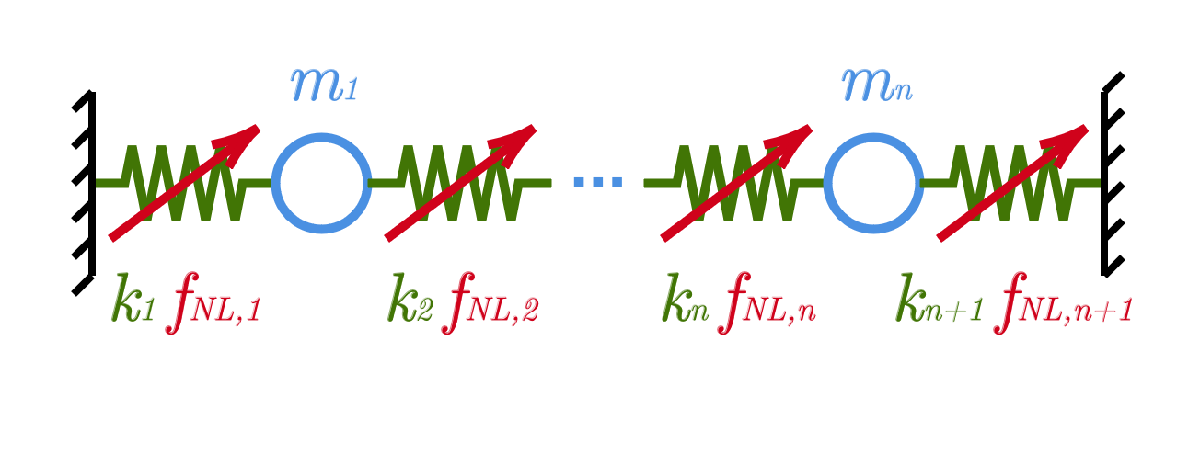

## Initialize

Include the function folder.

addpath(genpath(fullfile('..', 'LSM-opt-functions')))

## Settings

Define the type of the system.

sysArgs.systemType = @SystemSpringMassChain;

Define the boundary conditions: 0 to fix the mas, 1 to let it free.

sysArgs.bc = [0, ones(1, 3), 0];
nMasses = sum(sysArgs.bc);
nSprings = nMasses + 1;

Define the index of the target mode.

sysArgs.modeIndex = 1;

Define the LSM arguments, i.e., the target dof of the system and the LSM expansion order.

lsmArgs.iDof = 2;
lsmArgs.order = 5;

## Optimization problem

The objective function and the nonlinear constraints are defined in the `fun` and `nonlcon` functions in this folder. 

Define the target points as frequency - amplitude pairs.

optArgs.omegaTarget = [2, 1.9, 2.1];
optArgs.zTarget = [0, 1.5, 2];

Specify if the frequency - amplitude pairs are treated as equality constraint (0), upper inequality constraint (1), or lower inequality constraint (-1).

optArgs.coeffTarget = [0, 1, -1];

Define the initial conditions for the design variables.

x0u = [3, 30, 3, 3];
x0 = [x0u(1) * ones(1, nMasses), ...
      x0u(2) * ones(1, nSprings), ...
      x0u(3) * ones(1, nSprings), ...
      x0u(4) * ones(1, nSprings)];

Define the lower and upper bounds for the design variables.

xlu = [1, 10, 0.1, 0.1] * 0.5; % relax the lower bounds
xuu = [10, 50, 5, 5] * 1.5; % relax the upper bound
xl = [xlu(1) * ones(1, nMasses), ...
      xlu(2) * ones(1, nSprings), ...
      xlu(3) * ones(1, nSprings), ...
      xlu(4) * ones(1, nSprings)];
xu = [xuu(1) * ones(1, nMasses), ...
      xuu(2) * ones(1, nSprings), ...
      xuu(3) * ones(1, nSprings), ...
      xuu(4) * ones(1, nSprings)];

Define the linear equality and inequality constraints (if any).

A = []; b = [];
Aeq = []; beq = [];

## Optimizer options

In this work, `fmincon` is used to solve the nonlinear optimization problem.

Define below the required options

options = optimoptions('fmincon', 'Display', 'iter');
options.Algorithm = "interior-point";
options.EnableFeasibilityMode = true;
options.SpecifyObjectiveGradient = true;
options.SpecifyConstraintGradient = true;

## Solve the optimization problem

Solve the optimization problem.

tStart = tic;
[x, fval] = fmincon(@(x) fun(x, nMasses, nSprings), x0, A, b, Aeq, beq, xl, xu, @(x) nonlcon(x, sysArgs, lsmArgs, optArgs), options);

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1    3.000000e+00    6.816e-01    3.672e-01
    1       3    3.155251e+00    6.180e-01    4.120e-01    2.643e-01
    2       5    3.205841e+00    5.822e-01    4.430e-01    1.849e-01
    3       7    3.195062e+00    5.604e-01    4.658e-01    1.706e-01
    4       8    3.200393e+00    5.045e-01    5.035e-01    7.548e-01
    5       9    3.184153e+00    2.744e-01    5.881e-01    3.661e+00
    6      11    3.184593e+00    2.729e-01    5.887e-01    1.620e-02
    7      12    2.930708e+00    2.611e-01    6.079e-01    9.840e-01
    8      13    1.155573e+00    1.214e-01    7.384e-01    5.388e+00
    9      14    7.060641e-01    1.635e-01    7.604e-01    9.426e-01
   10      16    7.037851e-01    1.636e-01    7.606e-01    6.934e-03
   11      18    6.813823e-01    1.635e-01    7.626e-01    1.086e-01
   12      19    5.009069e-01    1.603e-01    7

tElapsed = toc(tStart);
disp(['Elapsed time is ', num2str(tElapsed, '%.2f'), ' seconds.'])

Elapsed time is 10.67 seconds.


disp('Optimal solution:')

Optimal solution:


disp(['Mass: ', num2str(x(1:nMasses))])

Mass: 3.6936     0.50016      2.3039


disp(['Linear spring: ', num2str(x(nMasses+(1:nSprings)))])

Linear spring: 7.51118      28.4922      24.1043      32.1369


disp(['Quadratic spring: ', num2str(x(nMasses+nSprings+(1:nSprings)))])

Quadratic spring: 5.8909      3.5111      1.9084      5.8727


disp(['Cubic spring: ', num2str(x(nMasses+2*nSprings+(1:nSprings)))])

Cubic spring: 0.69007      1.4465      5.9104     0.95731


## Post processing

Build the system and perform the eigenvalue analysis.

sys = feval(sysArgs.systemType, x, sysArgs);
sys = sys.modal_analysis();

Identify the master mode. In this case, it's the first one.

sys.omega0 = sys.omega(sysArgs.modeIndex);
sys.phi0 = sys.phi(:, sysArgs.modeIndex);
sys = sys.state_space_modal_analysis();

Build the LSM.

lsm = LSM(sys, lsmArgs.order);
lsm = lsm.compute_manifold();

Compute the backbone points.

rhoTarget = lsm.solve_rho(optArgs.zTarget, lsmArgs.iDof);
rho = linspace(0, max(rhoTarget), 51);
z = lsm.compute_z(rho, lsmArgs.iDof);
omega = lsm.compute_omega(rho);

Plot the backbone curve with the target points.

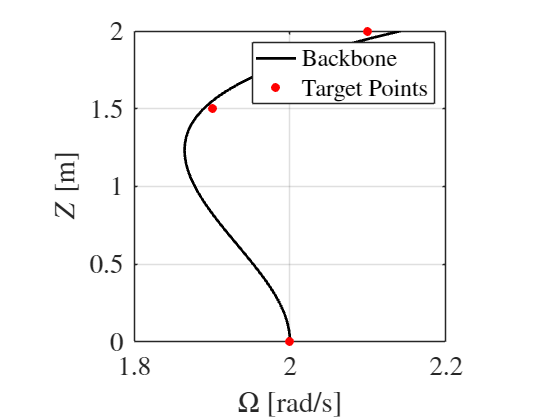

figure();
plot_backbone(omega, z, optArgs.omegaTarget, optArgs.zTarget);